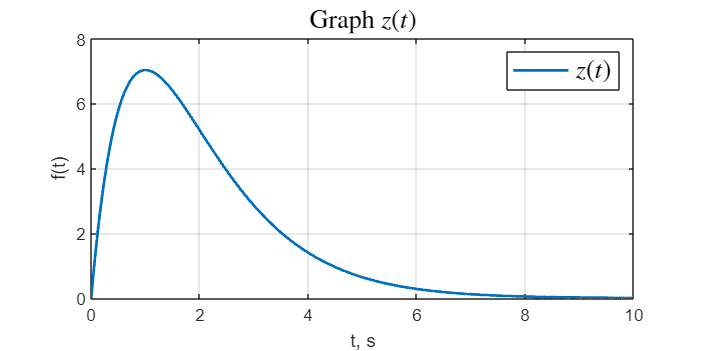

% что-то про симуляцию

open_system('task_4_sim');
set_param('task_4_sim/w', 'VariableName', 'w');
set_param('task_4_sim/z', 'VariableName', 'z');
set_param('task_4_sim/g', 'VariableName', 'g');
set_param('task_4_sim/y1', 'VariableName', 'y1');
set_param('task_4_sim/u', 'VariableName', 'u');
set_param('task_4_sim/x', 'VariableName', 'x');
out = sim('task_4_sim');

figure('Position', [100 100 800 400])
plot(out.z,'-', 'LineWidth',1.5);
grid()
title('Graph $z(t)$','Interpreter','latex',  'FontSize', 14)
legend('$z(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')

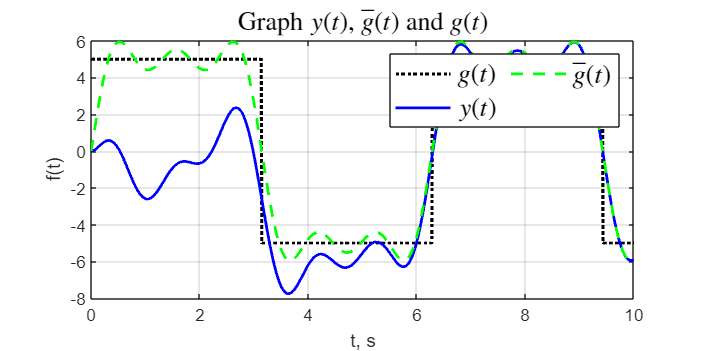




%y = (10/pi) * (2*sin(t) + (2/3)*sin(3*t) + 2/5*sin(5*t));

figure('Position', [100 100 800 400])
%plot(out.x.Time, out.x.Data(:,1),'-', 'LineWidth',1.5);
plot(t, g_f(t),'k:', 'LineWidth',1.7);
hold on
plot(out.y1,'b-', 'LineWidth',1.5);
plot(out.g,'g--', 'LineWidth',1.5);

grid()
title('Graph $y(t)$, $\bar{g}(t)$ and $g(t)$','Interpreter','latex',  'FontSize', 14)
legend('$g(t)$','$y(t)$', '$\bar{g}(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
hold off

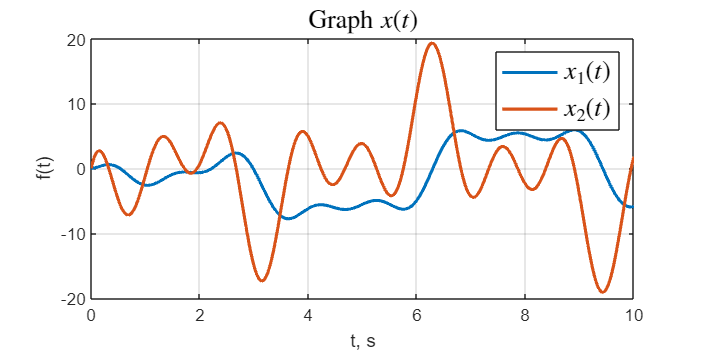


figure('Position', [100 100 800 400])
plot(out.x, 'LineWidth',1.7);

grid()
title('Graph $x(t)$','Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$','$x_2(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')

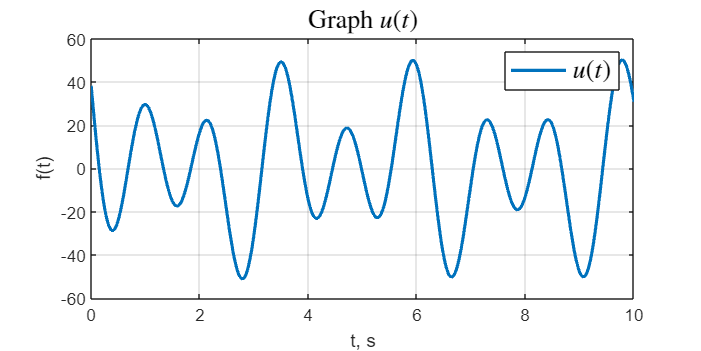


figure('Position', [100 100 800 400])
plot(out.u, 'LineWidth',1.7);

grid()
title('Graph $u(t)$','Interpreter','latex',  'FontSize', 14)
legend('$u(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')

function y = g_f(t)
    y = zeros(size(t)); % Инициализация выходного массива
    ind = ceil(size(t) / pi);
    for k = 0:ind
    % Определение значений функции на разных интервалах
        y(t >= (2*k + 1)* pi & t < 2*(k + 1)*pi) = -5;
        y(t >= 2*(k)*pi & t < (2 * (k + 1) - 1)*pi) = 5;
    end
end

